%specify roots
%r = sym('r',[1 2])
roots = [ 10 20 30 40 50 60 70]

roots =     10    20    30    40    50    60    70


%get rate from roots
poly = -1;
x = sym('x');
for i = 1:size(roots,2)
    poly = poly*(x-roots(i));
end
%poly

%poly_func = matlabFunction(poly)

%Get rate cosntants 
C = coeffs(poly,x)

$$C = \left(\begin{array}{cccccccc} 50400000000 & -13068000000 & 1313200000 & -67690000 & 1960000 & -32200 & 280 & -1 \end{array}\right)$$

k_const = abs(C)

$$k\_const = \left(\begin{array}{cccccccc} 50400000000 & 13068000000 & 1313200000 & 67690000 & 1960000 & 32200 & 280 & 1 \end{array}\right)$$

%find the ratios of the coefficients
qsize = floor(size(k_const,2)/2);
qs = zeros(qsize,1);
for i = 1:qsize
    qs(i) = k_const(2*i-1)/k_const(2*i);
end
qs

qs =     3.8567
   19.4002
   60.8696
  280.0000


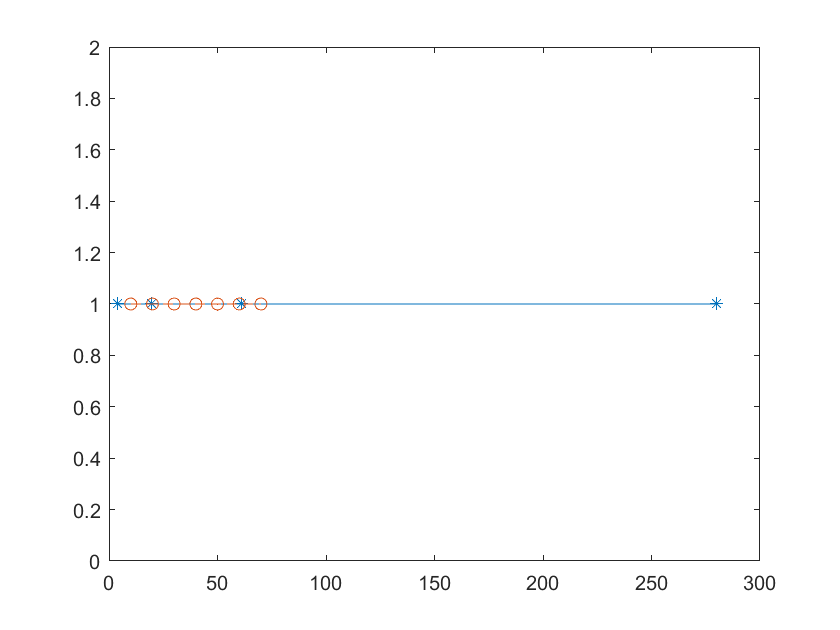

figure()
plot(qs,ones(size(qs)),'*-')
hold on
plot(roots,ones(size(roots)),'o--')
hold off


trans(roots(3),qs,2,2)/trans(roots(3),qs,3,3)

ans = -0.2011


trans(roots(4),qs,2,2)/trans(roots(4),qs,3,3)

ans = -0.5780


trans(roots(5),qs,2,2)/trans(roots(5),qs,3,3)

ans = -1.6484

trans(roots(7),qs,2,3)/trans(roots(7),qs,4,4)

ans = -0.1188


trans(roots(5),qs,2,2)/trans(roots(5),qs,3,4)

ans = -0.0487

function tot_trans = trans(x,l,i,j)
    tot_trans = 0;
    for k = i:j
        tot_trans = tot_trans + (x-l(k))*log(l(1)/l(k));
    end
end